# Beamforming in Multi-Path Channels at 28 GHz

Beamforming is a key component of many 5G technologies including massive MIMO and mmWave communication.  In this lab, we will show how to simulate beamforming in frequency domain.  We will use typical arrays for 28 GHz.

In going through this lab, you will learn to:

- Construct antenna elements and arrays

- Visualize the element gain pattern and array gain

- Normalize array patterns to account for mutual coupling

- Select beamforming vectors to align to particular paths

- Compute the MIMO channel response in an OFDM system

- Compute the gain in SNR due to element gain and beamforming

- Compare constant beamforming and instantaneous beamforming

Also, along with this file, you will have to make modifications for these files:

- `ArrayPlatform.m`:  A class for an array platform that stores the element, array and local to global coordinate system mapping, It performs the normalization for antenna patterns

- `FDMIMOChan.m`:  A class for frequency-domain MIMO channel simulation

**Submission**:  Complete the files.  Run the code.  Print the outputs to PDF.  Combine all files to a single PDF and submit the PDF.  Do not submit any other source code.

## Creating the Antenna Elements

We will use a simple patch microstrip antenna element which are typical at 28 GHz.

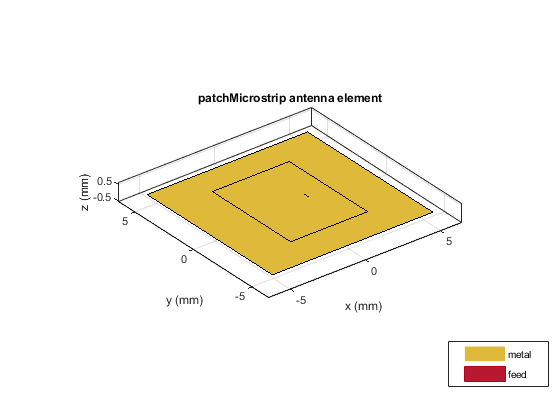

fc = 28e9;  % Carrier frequency
elem = design(patchMicrostrip, fc);
show(elem);

The element is constructed with the boresight in the positive z-axis.  Use the `elem.Tilt` and `elem.TiltAxis` to rotate the element so that the boresight is along the x-axis.

% TODO:
elem.Tilt = 90;
elem.TiltAxis = [0, 1, 0];

Use the `elem.show() and `view` commands to see the antenna element in 3D see the front face of the patch.

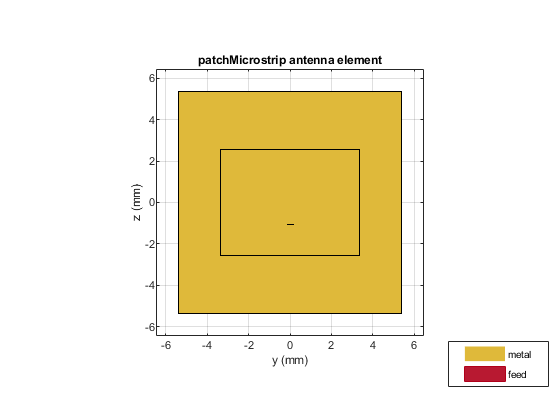

% TODO
elem.show();
view([90 0]);

Display the directivity pattern of the antenna with `elem.pattern` command.  You should see that this is a highly directive antenna with 10.1 dBi gain.

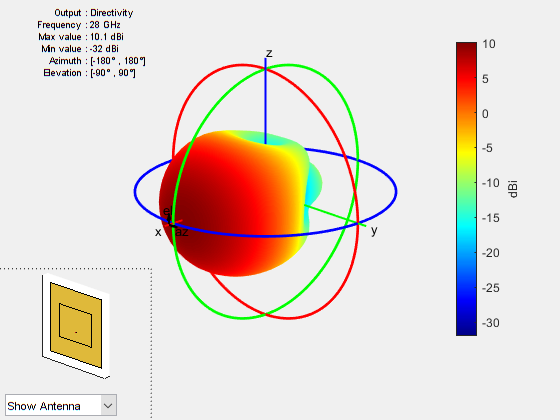

% TODO
figure;
elem.pattern(fc);

## Creating the Antenna Arrays

We next construct the arrays at the gNB and UE.  Consruct two URA with the given array dimensions.  Use a lambda / 2 separation.

% Number of antennas 
nantgNB = [4,4];
nantUE = [2,2];
lambda = physconst("Lightspeed")/fc;

% TODO:  Construct a URA
arrgNB = phased.URA(nantgNB, lambda/2, 'Element',elem);
arrUE = phased.URA(nantUE, lambda/2, 'Element',elem);

## Creating the Array Platform

I have created a skeleton class, `ArrayPlatform, `that performs several useful tasks for the array managment:

- Stores the element and array structure

- Computes the normalization matrix to account for mutual coupling

- Computes the normalized steering vectors in a given set of angles

The main function to be completed is `computeNormMatrix()` method.  

Next, complete the `step` method that produces the steering vectors and element gain for a given set of angles.

Once you have completed this method, you can build the array platform with the functions

arrPlatformgNB = ArrayPlatform('elem', elem, 'arr', arrgNB, 'fc', fc);
arrPlatformgNB.computeNormMatrix();

arrPlatformUE = ArrayPlatform('elem', elem, 'arr', arrUE, 'fc', fc);
arrPlatformUE.computeNormMatrix();

We now display the array patterns for different steering angles.  We will do this just for the gNB array.  First, complete the following code that get beamforing vectors on two different angles.  

% Angles to get the beamforming vectors
az0 = [0, 60];
el0 = [0, -20];
nw = length(az0);

% TODO:  Get the steering vectors for the angles using the step function
[svTx, gains] = arrPlatformgNB.step(az0, el0, true);

% TODO:  Get the BF vectors by taking the conjugate of each SV
% and normalizing
w = zeros(size(svTx));
for i=1:nw
    w_b = conj(svTx(:,i));
    w(:,i) = w_b / norm(w_b);
end
disp(norm(w(:,1))); 

     1



Next, complete the following code to plot the array patterns.

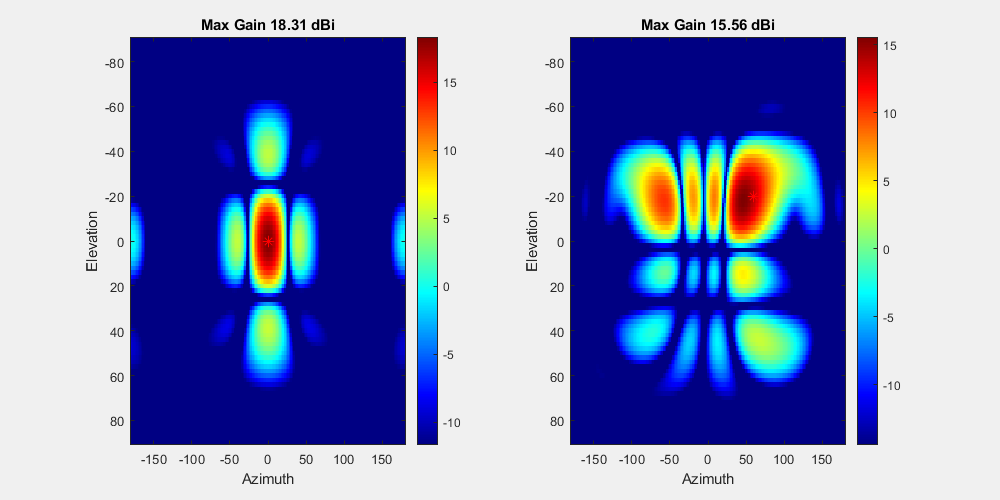

% Angles to plot the array pattern
az = (-180:2:180)';
el = (-90:2:90)';
naz = length(az);
nel = length(el);

% Get grid of values
[azMat, elMat] = meshgrid(az, el);
azVal = azMat(:);
elVal = elMat(:);

% TODO:  Get the normalized steering vectors at each of the plot angles
Sv = arrPlatformgNB.step(azVal', elVal', true);

clf;
posOld = get(gcf, 'Position');
set(gcf,'Position', [0,0,1000,500]);

% Loop over the beamforming vectors
for i = 1:nw
    
    w_b = w(:, i);        
    % TODO:  Find the array gain by taking the inner product of BF vector
    % w(:,i) with the steering vectors.  Convert the gain to dBi.    
    gain = mag2db(abs(sum(w_b.*Sv,1)));
    
    % TODO:  Find the maximum gain 
    gainMax = max(gain);
    
    % TODO:  Reshape the gain to a nel x naz matrix
    gain = reshape(gain,nel,naz);
    
    % TODO:  Plot the gain on a subplot. using imagesc()
    %   Set the color limits to [gainMax-30, gainMax]
    %   Add a colorbar
    %   Label the axes
    %   Place a marker on the intended maximum direction
    subplot(1,2,i);
    imagesc(az,el,gain,[gainMax-30 gainMax]); hold on;
    plot(az0(i), el0(i), "Marker","*","MarkerSize",8,"MarkerFaceColor",'r',"MarkerEdgeColor",'r'); hold off;
    title(sprintf("Max Gain %3.2f dBi", gainMax));
    xlabel("Azimuth"); ylabel("Elevation");
    colorbar();
end

## Visualizing Beamforming Gains on the Channel Paths

We will now compute the gains on a multi-path channel.  We use the 3GPP CDL-C model.  The path parameters can be obtianed in MATLAB as follows.

dlySpread = 100e-9;  % delay spread in seconds
chan = nrCDLChannel('DelayProfile','CDL-C',...
    'DelaySpread',dlySpread, 'CarrierFrequency', fc, ...
    'NormalizePathGains', true);
chaninfo = info(chan);

gain = chaninfo.AveragePathGains';
aoaAz  = chaninfo.AnglesAoA';
aoaEl = 90-chaninfo.AnglesZoA';
aodAz  = chaninfo.AnglesAoD';
aodEl = 90-chaninfo.AnglesZoD';
dly = chaninfo.PathDelays';

To visualize the gains, create two  stem plots.  

- Gain vs. aodAz

- Gain vs. aoaAz

Use the subplots to put the gains side by side.  Also, set the `BaseValue` to -30 to clip very low gains.  This is the omni-directional gains before element or beamforming gain has been applied.

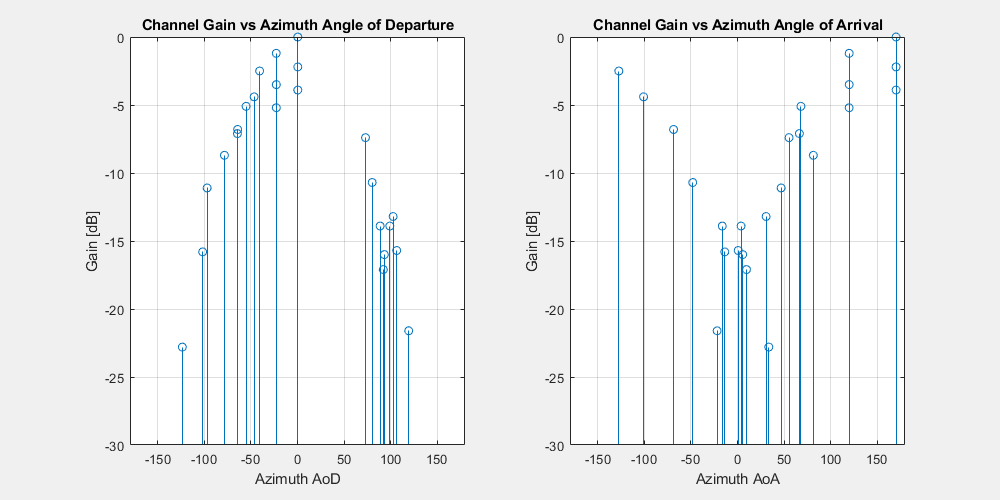

% TODO
clf; 
set(gcf,'Position', [0,0,1000,500]);
subplot(1,2,1);
stem(aodAz, gain, "BaseValue",-30); grid on;
xlabel("Azimuth AoD"); ylabel("Gain [dB]"); xlim([-180 180]);
title("Channel Gain vs Azimuth Angle of Departure");
subplot(1,2,2);
stem(aoaAz, gain, "BaseValue",-30); grid on;
xlabel("Azimuth AoA"); ylabel("Gain [dB]");
title("Channel Gain vs Azimuth Angle of Arrival"); ylim([-30, 0]); xlim([-180 180]);

We now rotote the UE to an angle of 135 degrees which is close to the main angle of arrival. 

azUE = 135;
elUE = -10;
arrPlatformUE.alignAxes(azUE, elUE);

Next, get the TX element gains and steering vectors along the AoD and the RX element gains and steering vectors along the AoAs.

% TODO:
[svTx, elemGainTx] = arrPlatformgNB.step(aodAz',aodEl',true);
[svRx, elemGainRx] = arrPlatformUE.step(aoaAz',aoaEl',true);

Get the gains along the paths with the element gains but without any array gain.  

% TODO:
gainElem = gain + elemGainTx' + elemGainRx';

Create the same stem plot as before, but on each subplot, plot both `gain` and `gainElem` to see the effect of the element gains.  You will see that a few paths are much more pronounced in gain.

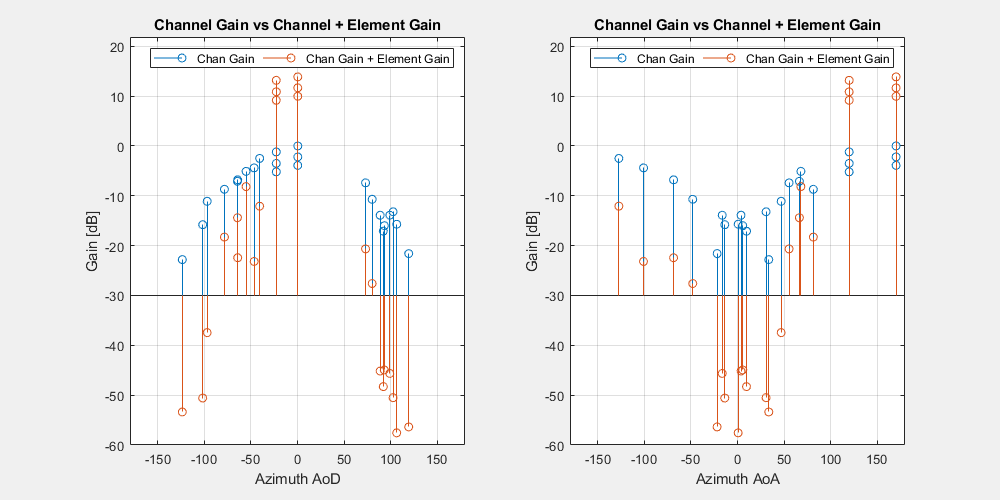

% TODO
clf; 
set(gcf,'Position', [0,0,1000,500]);

subplot(1,2,1);
stem(aodAz, gain, "BaseValue",-30); hold on;
stem(aodAz, gainElem, "BaseValue",-30); grid on; hold off;
xlabel("Azimuth AoD"); ylabel("Gain [dB]"); 
ylim([-60, max(gainElem)+8]); 
xlim([-180 180]);
legend("Chan Gain","Chan Gain + Element Gain", "Orientation","horizontal");
title("Channel Gain vs Channel + Element Gain");

subplot(1,2,2);
stem(aoaAz, gain, "BaseValue",-30); hold on;
stem(aoaAz, gainElem, "BaseValue",-30); grid on; hold off;
xlabel("Azimuth AoA"); ylabel("Gain [dB]");
ylim([-60, max(gainElem)+8]); 
xlim([-180 180]);
legend("Chan Gain","Chan Gain + Element Gain", "Orientation","horizontal");
title("Channel Gain vs Channel + Element Gain");

As a simple example for the beamforing, find the path index `i` where  `gainElem(i)` is maximized.  Then find TX and RX beamforming vectors, `wtx` and `wrx` aligned to the conjugate of the normalized spatial signatures on this path.

% TODO
[~, max_ind] = max(gainElem);
w_b = conj(svTx(:, max_ind));
wtx = w_b / norm(w_b);
w_b_rx = conj(svRx(:, max_ind));
wrx = w_b_rx / norm(w_b_rx);

Find the gain along each path using the BF vectors from above.  Then create the same stem plot as before.  You should see that, after the beamforming, there is one path that is dominant.

% TODO:  Find the gain along each path
gainBFtx = mag2db(abs(sum(wtx.*svTx,1)))';
gainBFrx = mag2db(abs(sum(wrx.*svRx,1)))';
gainArr = gainElem + gainBFtx + gainBFrx;

% TODO:  Create the stem plots
clf; 
set(gcf,'Position', [0,0,1000,500]);

subplot(1,2,1);
stem(aodAz, gain, "BaseValue",-30); hold on;
stem(aodAz, gainElem,"BaseValue",-30); hold on; grid on; 
stem(aodAz, gainArr,"BaseValue",-30); hold off;
xlabel("Azimuth AoD"); ylabel("Gain [dB]"); 
%ylim([-40, max(gainArr)+8]); 
xlim([-180 180]);
legend("Chan Gain","Chan Gain + Elem Gain", "Chan Gain + Elem Gain + BF Gain", "Orientation","vertical","Location","southoutside");
title("Chan Gain vs Chan + Elem Gain vs Chan + Elem + BF Gain");

subplot(1,2,2);
stem(aoaAz, gain,"BaseValue",-30); hold on;
stem(aoaAz, gainElem,"BaseValue",-30); hold on; grid on; 
stem(aoaAz, gainArr,"BaseValue",-30); hold off;
xlabel("Azimuth AoA"); ylabel("Gain [dB]");
%ylim([-40, max(gainArr)+8]); 
xlim([-180 180]);
legend("Chan Gain","Chan Gain + Elem Gain", "Chan Gain + Elem Gain + BF Gain", "Orientation","vertical","Location","southoutside");
title("Chan Gain vs Chan + Elem Gain vs Chan + Elem + BF Gain");

## Visualizing the OFDM Channel

We conclude by visualizing the OFDM channel with and without beamforming.  We use the following parameters

fc = 28e9;                  % Carrier frequency
SubcarrierSpacing = 120;    % SCS in kHZ
NRB = 61;  % number of resource blocks
nscPerRB = 12;  % number of sub-carriers per RB

Similar to the previous lab, we get the `carrierConfig` and `waveformConfig` with the `nrCarrierConfig` and `nrOFDMInfo` methods in the 5G Toolbox.

carrierConfig = nrCarrierConfig('NSizeGrid', NRB, 'SubcarrierSpacing', SubcarrierSpacing);
waveformConfig = nrOFDMInfo(carrierConfig);

Complete the MIMO channel object, `FDMIMO` which produces a OFDM-MIMO channel matrix.

Once this class is completed, we can create the channel for one slot as follows.

Enoise = -5;  % Energy per noise sample in dB
fdchan = FDMIMOChan(carrierConfig, 'txArrPlatform', arrPlatformgNB, 'rxArrPlatform', arrPlatformUE, ...
    'aoaAz', aoaAz, 'aodAz', aodAz, 'aoaEl', aoaEl, 'aodEl', aodEl,  ...
    'gain', gain, 'dly', dly, 'fc', fc, 'Enoise', Enoise);

frameNum = 0;
slotNum = 0;
[chanGrid, noiseVar] = fdchan.step(frameNum, slotNum);

The above command should yield an array chanGrid of size `nrx x ntx x nsc x nt` representing the MIMO channel matrix components over frequency and time.  Plot the SNR per resource element for the channel along a single TX and RX antenna pair, say `chanGrid(3,4,:,:)`.  Plot the SNR in dB scale using the `imagesc` command so it can be visualized in time and frequency.

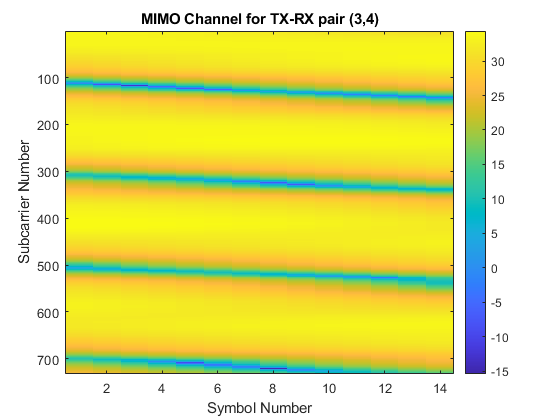

% TODO:
figure;
sub_chanGrid = reshape(chanGrid(3,4,:,:),nscPerRB*NRB,14);
snrSing = pow2db(abs(sub_chanGrid).^2/noiseVar);
imagesc(snrSing);
colorbar();
xlabel("Symbol Number"); ylabel("Subcarrier Number");
title("MIMO Channel for TX-RX pair (3,4)");

## OFDM Beamforming

We next compute the SNR using instantaneous BF.  For each point `chanGrid(:,:,n,t), `find the maximum gain with BF using the SVD.  Plot the resulting SNR.  You should see that the resulting SNR is much higher and varies very little over time and frequency.  

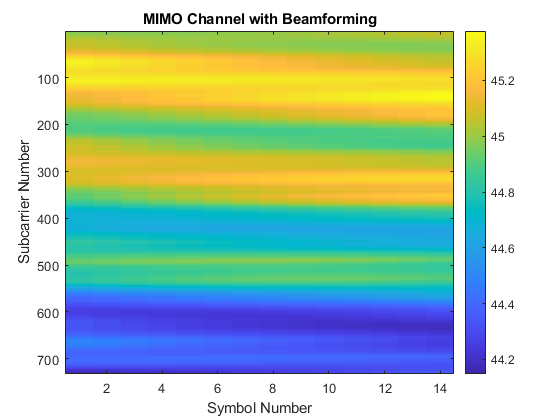

% TODO:
nrx = arrPlatformUE.getNumElements();
ntx = arrPlatformgNB.getNumElements();
chan_BF = zeros(nscPerRB*NRB,14);
chan_prof = zeros(nscPerRB*NRB,14);
for i=1:nscPerRB*NRB
    for j=1:14
        H = reshape(chanGrid(:,:,i,j), nrx,ntx);
        [U,S,V] = svd(H);
        s_values = svd(H);
        wrx = U(:,1);
        wtx = V(:,1);
        c_bf = wrx'*H*wtx;
        chan_BF(i,j) = c_bf;
        chan_prof(i,j) = s_values(1);
    end
end

figure;
snrInst = pow2db(abs(chan_BF).^2/noiseVar);
imagesc(snrInst);
colorbar();
xlabel("Symbol Number"); ylabel("Subcarrier Number");
title("MIMO Channel with Beamforming");